a) Plot the square wave

[time_pos, sq_wave, B_unnorm] = generate_data;

figure;
subplot(4,2,1);
plot(time_pos, sq_wave);
title("Plot of square wave");
xlabel('Time');
axis([0 20 -0.75 0.75]);

b) How would you numerically test for the orthogonality of the basis vectors (rows of B unnorm)? Plot the first 6 and 30th basis vectors against time pos in separate sub-plots that share the same time axis. 

I would test for the orthogonality by computing the inner product of each pair of basis vectors. For orthogonality, the inner product must be zero.

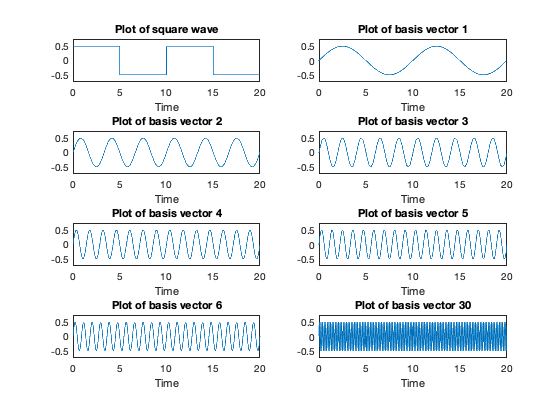

%each basis vector is a row in B_unnorm
%each basis vector shares the same length/dimensionality as sq_wave
%plot the first 6 and 30th basis vectors
for i=1:6
    subplot(4,2,i+1);
    plot(time_pos, B_unnorm(i,:));
    title_name = sprintf("Plot of basis vector %d", i);
    title(title_name);
    xlabel('Time');
    axis([0 20 -0.75 0.75]);
end
subplot(4,2,8);
plot(time_pos, B_unnorm(30,:));
title_name = sprintf("Plot of basis vector %d", 30);
title(title_name);
xlabel('Time');
axis([0 20 -0.75 0.75]);

c) Normalize the given basis vectors to obtain an orthonormal basis. Project the square wave signal onto the normalized basis vectors using l2 projection and compute the projection coefficients. Arrange the basis vectors in the decreasing order of the magnitude of the projection coefficients. Approximate the square wave using the first 1,2,3,4,5,6,30 basis vectors, and plot the approximations in separate sub-plots that share the same time axis. Plot the original signal on top of each approximation and compare.

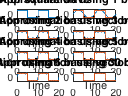

%normalize basis vectors
%divide each basis vector by its magnitude
B_norm = B_unnorm;
for i=1:size(B_unnorm,1)
    B_norm(i,:) = B_unnorm(i,:)./norm(B_unnorm(i,:));
end

%with an orthonormal basis, coefficients for the linear combination of basis
%vectors to approximate the function is simply the inner/dot product of the
%fucntion with the respective basis vector
%let proj_coef by the projection coefficient for each basis vector
proj_coef = zeros(1, size(B_norm, 1));

for i=1:size(B_norm, 1)
    proj_coef(i) = dot(sq_wave,B_norm(i,:));
end

%sort by decreasing order of magnitude of projection coefficients
B_norm = [transpose(proj_coef), B_norm];
B_norm = sortrows(B_norm, 1, "descend");

%plot approximations using 1,2,3,4,5,6,30 basis vectors
figure
subplot(4,2,1);
plot(time_pos, sq_wave);
title("Plot of square wave");
xlabel('Time');
axis([0 20 -0.75 0.75]);

for i=1:6
    subplot(4,2,i+1);
    approx = zeros(1, size(B_norm,2)-1);
    for e=1:i
        approx = approx + B_norm(e,2:end) .* B_norm(e,1);
    end
    plot(time_pos, approx);
    hold on
    plot(time_pos, sq_wave);
    hold off
    title_name = sprintf("Approximation using %d basis vectors", i);
    title(title_name);
    xlabel('Time');
    axis([0 20 -0.75 0.75]);
end

subplot(4,2,8);
approx = zeros(1, size(B_norm,2)-1);
for e=1:30
    approx = approx + B_norm(e,2:end) .* B_norm(e,1);
end
plot(time_pos, approx);
hold on
plot(time_pos, sq_wave);
hold off
title_name = sprintf("Approximation using 30 basis vectors");
title(title_name);
xlabel('Time');
axis([0 20 -0.75 0.75]);

function [time_pos , sq_wave , B_unnorm] = generate_data
    n_comps = 30; period = 10; fundFreq = 1/period;
    time_pos = 0:0.0001:2*period; harmonics = 2*(1:n_comps)-1;
    sq_wave = floor(0.9*sin(2*pi*fundFreq*time_pos))+.5; %% generate the signal 
    B_unnorm = sin(2*pi*fundFreq*(harmonics'*time_pos))/2; %% generate the basis
end